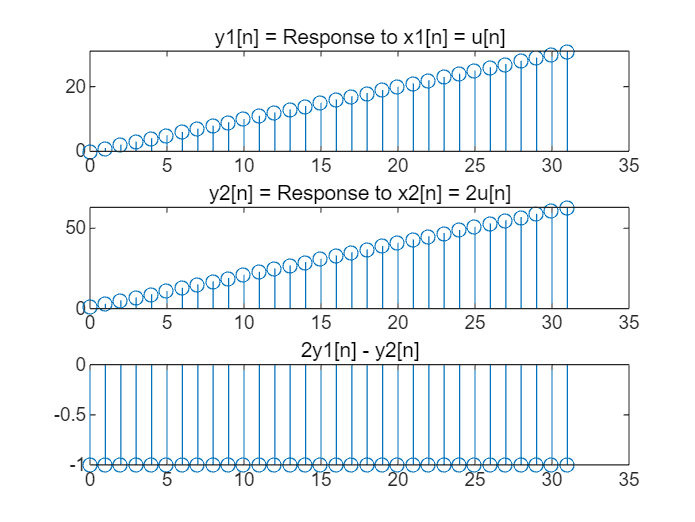

% 定义输入信号
x1 = ones(1, N+1); % u[n]
x2 = 2 * ones(1, N+1); % 2u[n]

% 计算响应
yn1 = -1; % y[-1]
y1 = diffeqn(a, x1, yn1);
y2 = diffeqn(a, x2, yn1);

% 绘制响应
figure;
subplot(3,1,1);
stem(0:N, y1);
title('y1[n] = Response to x1[n] = u[n]');
subplot(3,1,2);
stem(0:N, y2);
title('y2[n] = Response to x2[n] = 2u[n]');
subplot(3,1,3);
stem(0:N, 2*y1 - y2);
title('2y1[n] - y2[n]');


% 分析为什么 2y1[n] - y2[n] 不是恒等于零
% 由于差分方程是线性的，理论上 2y1[n] - y2[n] 应该恒等于零。
% 但是，由于初始条件 y[-1] 不同，导致了非零的差值。